% For the example, select a subset of the table to plot. Because the table
% is created with individual components for each cell, creating big tables
% take a significant amount of time. 
NumRowsToShow = 30; % Should be number from 1 to 100.

% Note: One idea for supporting large tables without affecting performance is 
% to create a paged table with a fixed number of rows per page.

% Check if the Ratings component is available.
isRatingComponentAvailable = exist('Rating', 'class') == 8;
if ~isRatingComponentAvailable
    fexUrl = "https://se.mathworks.com/matlabcentral/fileexchange/166231-rating-app-component";
    ratingLink = sprintf('<a src="%s">Rating</a>', fexUrl);
    weblink = sprintf('%s', fexUrl, 'Rating');
    warning('Rating component not found. To see an example with a custom component \nin this table, install the %s component from FileExchange.', weblink)
end


% Read the patients table
T = readtable('patients.xls', 'TextType', 'string'); 

% Add descriptions for each variable.
T.Properties.VariableDescriptions = [...
    "Person's last name (i.e family name)", ...
    "Gender of person", ...
    "The age in years", ...
    "Name of hospital", ...
    "Height of person in inches", ...
    "Weight of person in pounds", ...
    "Whether person smokes or not", ...
    "Systolic blood pressure (mm Hg)", ...
    "Diastolic blood pressure (mm Hg)", ...
    "Self assessed health score, can be excellent, good, fair, poor"];

% Change types for some of the variables.
T.Age = uint8(T.Age);
T.Weight = uint8(T.Weight);
T.Height = uint8(T.Height);
T.Systolic = uint8(T.Systolic);
T.Diastolic = uint8(T.Diastolic);

T.Gender = categorical(T.Gender);
T.SelfAssessedHealthStatus = categorical(T.SelfAssessedHealthStatus, {'Poor', 'Fair', 'Good', 'Excellent'});

if isRatingComponentAvailable
    T.Score = double(T.SelfAssessedHealthStatus);
    T = movevars(T, 'Score', 'After', 'Age');
end

T = T(1:NumRowsToShow,:);
T

T = 30×10 table
     LastName     Gender    Age             Location              Height    Weight    Smoker    Systolic    Diastolic    SelfAssessedHealthStatus
    __________    ______    ___    ___________________________    ______    ______    ______    ________    _________    ________________________

    "Smith"       Male      38     "County General Hospital"        71       176      true        124          93               Excellent        
    "Johnson"     Male      43     "VA Hospital"                    69       163      false       109          77               Fair             
    "Williams"    Female    38     "St. Mary's Medical Cent

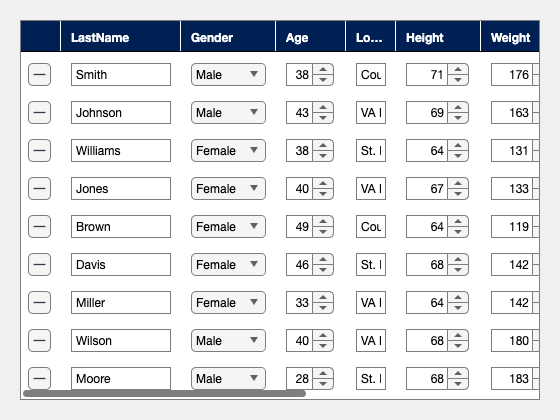

% Create a figure
f = uifigure('Name', 'Patients');
h = uigridlayout(f);
h.ColumnWidth = {'1x'};
h.RowHeight = {'1x'};
h.Padding = 20;

% Create the WidgetTable component
widgetTable = WidgetTable(h);


if isRatingComponentAvailable % Use the custom Rating component:
    widgetTable.ColumnWidth = {100, 75, 50, 100, '1x', 65, 65, 50, 75, 75, 100};
    ratingComp = @(comp, varargin) Rating(comp, ...
            'Reactive', 'off', ...
            'BackgroundColor', 'w', ...
            'NumStars', 4, ...
            'Tooltips', {'Poor', 'Fair', 'Good', 'Excellent'});
    
    widgetTable.ColumnWidget = {'', '', '', ratingComp, '', '', '', '', '', '', ''};
else
    widgetTable.ColumnWidth = {100, 75, 50, '1x', 65, 65, 50, 75, 75, 100};
end

widgetTable.Data = T;

if isRatingComponentAvailable
    widgetTable.CellEditedFcn = @onCellEdited;
end

widgetTable.HeaderBackgroundColor = "#002054";
widgetTable.HeaderForegroundColor = "w";
widgetTable.BackgroundColor = 'w';


% Callback function that makes sure the values for SelfAssessedHealthStatus and 
% the Score widget stay synchronized.


function onCellEdited(src, evt)
    varNames = src.Data.Properties.VariableNames;

    switch varNames{ evt.Indices(2) }
        case 'Score'
            dependentColumnIndex = find(strcmp(varNames, 'SelfAssessedHealthStatus'));
            src.updateCellValue(evt.Indices(1), dependentColumnIndex, evt.NewData);
        
        case 'SelfAssessedHealthStatus'
            dependentColumnIndex = find(strcmp(varNames, 'Score'));
            src.updateCellValue(evt.Indices(1), dependentColumnIndex, double(evt.NewData));
    end
end